.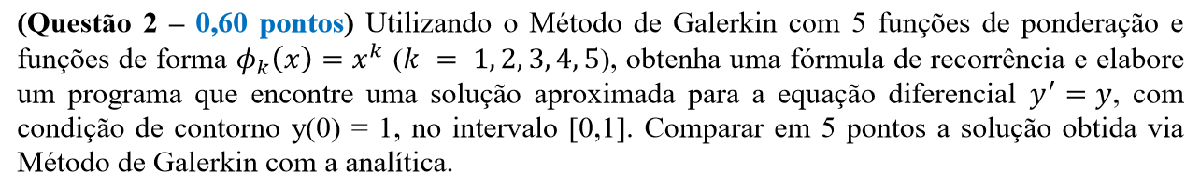

Método de Galerkin 

k = 5 , intervalo [0,1], C.C y(0)=1 


$$\begin{array}{l}
\phi_k \left(x\right)=x^k \\
\mathrm{y'}=y\text{  }\to \frac{\mathrm{y'}}{y}=1\text{   }\mathrm{resolvendo}\text{ }a\text{ }\mathrm{EDO}\to \int \frac{\mathrm{y'}}{y}\mathrm{dx}=\int 1\text{ }\mathrm{dx}\to \mathrm{ln}\left(y\right)=x\text{ }+C\to y=e^{x+C} \text{ }\to y=e^x e^C \\
y\left(0\right)=e^0 e^C =1\to e^C =1\text{ }\mathrm{aplicando}\text{ }o\text{ }\mathrm{ln}\text{ }\mathrm{em}\text{ }\mathrm{ambos}\text{ }\mathrm{os}\text{ }\mathrm{lados}\to \mathrm{ln}\left(e^C \right)=\mathrm{ln1}\to C=\mathrm{ln1}\to C=0\\
\mathrm{logo}\text{ }y=e^x \text{ }é\text{ }a\text{ }\mathrm{função}\text{ }\mathrm{analítica}\text{ }
\end{array}$$


Determinar uma função F(x) aproximada a função y(x) através do somatorio da função $\phi_k \left(x\right)$


$$\begin{array}{l}
F\left(x\right)=\sum_{k=0}^{5} A_k \phi_k \to F=\sum_{k=0}^{5} A_k x^k \text{ }\to F\left(x\right)=A_0 x^0 +A_1 x^1 +A_2 x^2 +A_3 x^3 +A_4 x^4 +A_5 x^5 \\
F\left(x\right)=A_0 +A_1 x^1 +A_2 x^2 +A_3 x^3 +A_4 x^4 +A_5 x^5 \to F\left(0\right)=1\text{ }\left(\text{sobra}\text{ }\text{apenas}\text{ }o\text{ }\text{termo}\text{ }\text{independente}\right)\to A_0 =1\\
F\left(x\right)=1+A_1 x+A_2 x^2 +A_3 x^3 +A_4 x^4 +A_5 x^5 \text{ }\text{ }\text{ }=1+\sum_{k=1}^{5} A_k x^k \text{    }\|\text{    }\text{ }\text{F'}\left(x\right)=A_1 +{2A}_2 x+{3A}_3 x^2 +{4A}_4 x^3 +{5A}_5 x^4 \text{ }=\sum_{k=1}^{5} A_k kx^{k-1} \\
\text{Se}\text{ }\text{y'}=y\text{ }\to \text{y'}-y=0\iff \text{Já}\text{ }\text{para}\text{ }a\text{ }\text{função}\text{ }\text{aproximada}\text{ }\text{F'}=F\to \text{F'}-F=R\left(x\right),\text{onde}\text{ }R\left(x\right)\text{ }é\text{ }o\text{ }\text{residuo}\text{ }\text{gerado}
\end{array}$$


Calculando R(x)


$$\begin{array}{l}
R\left(x\right)=\text{F'}-F\to R\left(x\right)=A_1 +{2A}_2 x+{3A}_3 x^2 +{4A}_4 x^3 +{5A}_5 x^4 -\left\lbrack 1+A_1 x^1 +A_2 x^2 +A_3 x^3 +A_4 x^4 +A_5 x^5 \right\rbrack =\sum_{k=1}^{5} A_k kx^{k-1} -1-\sum_{k=1}^{5} A_k x^k \\
R\left(x\right)=-1+\sum_{k=1}^{5} A_k \left({kx^{k-1} -x}^k \right)
\end{array}$$


Para a função de ponderação $\phi_k$com k de 1 a 5, 


$$\begin{array}{l}
\int_0^1 R\left(x\right)\phi_k \text{dx}=0\to \int_0^1 \left\lbrack -1+\sum_{k=1}^{5} A_k \left({kx^{k-1} -x}^k \right)\right\rbrack \phi_k \text{dx}\text{ }\\
\phi_k =x^k \text{ }
\end{array}$$


Com isso se percebe que para cada $\phi_k$ os coeficientes armazenados na matriz Rx :       ${\text{Rx}}_k =\int_0^1 \left(kx^{k-1} -x^k \right)x^k$    e o termo independente S : $S_k =\int_0^1 {-\left(-1\right)x}^k$

format long
Rx(1:5,1:5)=0;
S(1:5,1)=0;
for i=1:5
    for k = 1:5
   f = @(x)(((k*(x)^(k-1))-(x^k))*(x^i));
   Rx(i,k)= intrap(0,1,100,f);
    end 
    f=@(x)((x^i));
    S(i,1)= intrap(0,1,100,f);
end

Resolvendo o sistema pelo metodo de Eliminação de Gauss para solucionar o sistema e retonar respectivamente os valores de $A_i$ com i variando de 1 para 5 :

disp(Rx)

   0.166650000000000   0.416675000000000   0.550041667000000   0.633424999500000   0.690634521309500
   0.083325000000000   0.300016667000000   0.433391666500000   0.523926188809500   0.589477375535750
   0.049991667000000   0.233358333500000   0.357217856309500   0.446570234345250   0.514113878972417
   0.033325000500000   0.190509523809500   0.303663093154750   0.389055548555667   0.455813872556167
   0.023801191309500   0.160755951964250   0.263997218138917   0.344636099444833   0.409382550759076



disp(S)

   0.500000000000000
   0.333350000000000
   0.250025000000000
   0.200033333000000
   0.166708332500000



A = metgauss(Rx,S)

A =    1.000190328887869   0.498433619209291   0.172043895042233   0.033066270671786   0.014562174039303


Logo a função F :


$$F=1+\text{ }1\ldotp 0002x+0\ldotp 4984x^2 +0\ldotp 1720x^3 +0\ldotp 0331x^4 \text{ }+0\ldotp 0146x^5$$


F = @(x)(1+x*A(1)+(x^2)*A(2)+(x^3)*A(3)+(x^4)*A(4)+(x^5)*A(5));
y = @(x)((exp(1))^x);

Comparação dos valores da função exata y com os da função aproximada F :

T2=cell(6,3);
T2(1,1)={'Xi'};
T2(1,2)={'Y(Xi)'};
T2(1,3)={'F(Xi)'};
aux=(1-0)/(5+1); %espaçamento
xi(1:5)=0; %Os 5 pontos selecionados estão  no vetor xi, determinado pelo espaçamento 'aux'
for i=1:5
    xi(i)=i*aux;  %vetor que guarda os pontos
    T2(i+1,1)={xi(i)};
    T2(i+1,2)={y(xi(i))};
    T2(i+1,3)={F(xi(i))};  
end
clear A aux f F i Rx k S T xi y;
disp(T2)

    'Xi'                   'Y(Xi)'                'F(Xi)'            
    [0.166666666666667]    [1.181360412865646]    [1.181367652778739]
    [0.333333333333333]    [1.395612425086090]    [1.395618437860094]
    [0.500000000000000]    [1.648721270700128]    [1.648730765982251]
    [0.666666666666667]    [1.947734041054676]    [1.947744836045195]
    [0.833333333333333]    [2.300975890892825]    [2.300987360018728]

